参考MATLAB官方示例：[https://ww2.mathworks.cn/help/optim/examples/travelling-salesman-problem.html](https://ww2.mathworks.cn/help/optim/examples/travelling-salesman-problem.html)

分枝定界法

clc;
clf;
all clear;
%load("50_cities.mat");
load("x500.mat");
cities = cityXY;
stopsX = cities(1, :)'; % Allocate x-coordinates of nStops
stopsY = cities(2, :)'; % Allocate y-coordinates
nStops = size(stopsX, 1);

idxs = nchoosek(1:nStops, 2);   % 构建所有点之间的配对可能
dist = hypot(stopsX(idxs(:, 1)) - stopsX(idxs(:, 2)), stopsY(idxs(:, 1)) - stopsY(idxs(:, 2)));     % 计算所有配对之间的距离
lendist = length(dist);

假设我们最后优化得到的轨迹为trajectory（0-1矢量，指示连接哪些配对），则轨迹长度为：dist' * trajectory

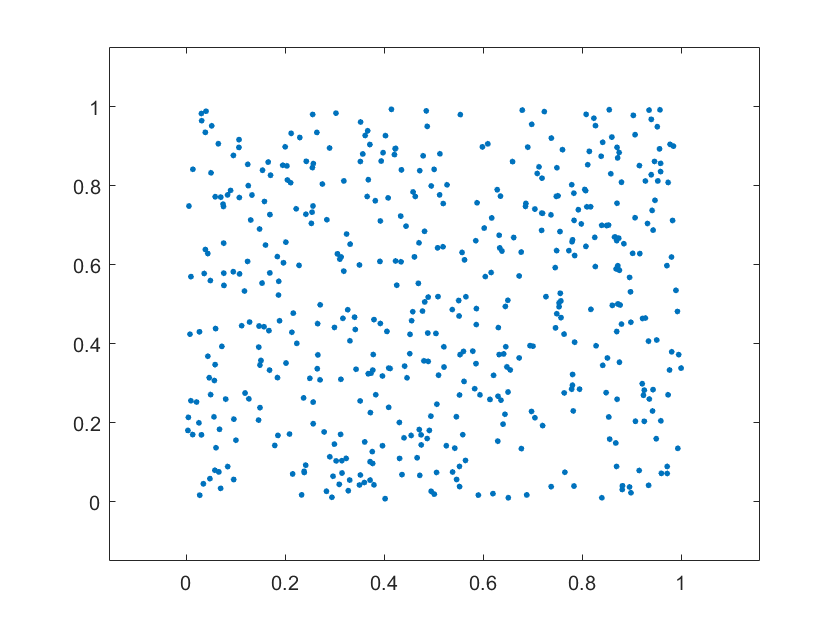

G = graph(idxs(:, 1), idxs(:, 2));      %创建包含所有可能连接关系的图
hGraph = plot(G, 'XData',stopsX, 'YData',stopsY, "LineStyle","none");   % 当前图中包含了所有连接关系

% 创建优化变量以及优化问题
tsp = optimproblem;
trajectory = optimvar('trajectory', lendist, 1, 'Type',"integer", 'LowerBound',0, "UpperBound",1);
tsp.Objective = dist' * trajectory;

% 约束条件为图中每个点应该属于两条边 
constraints = optimconstr(nStops, 1);
for i = 1:nStops
    whichIdxs = outedges(G, i);      % 从节点i出去的所有边
    constraints(i) = sum(trajectory(whichIdxs)) == 2;       % 有两条边出去
end

tsp.Constraints.constr2trips = constraints;

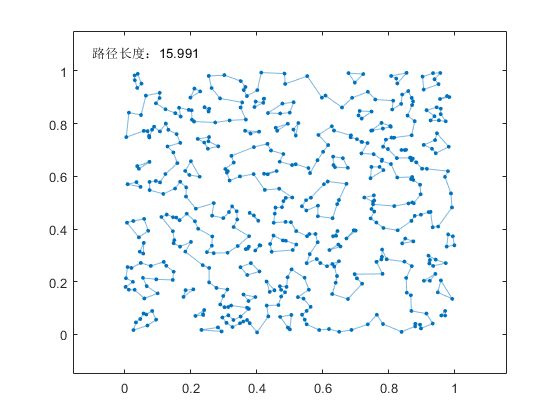

% 第一次尝试求解
options = optimoptions('intlinprog', 'Display',"off");  
solution = solve(tsp, 'options', options);

clf;
solution.trajectory = logical(round(solution.trajectory));  
Gsol = graph(idxs(solution.trajectory, 1), idxs(solution.trajectory, 2));

hGraph = plot(G, 'XData',stopsX, 'YData',stopsY, "LineStyle","none", 'NodeLabel',{});
hold on;
highlight(hGraph, Gsol, 'LineStyle',"-");
text(-0.1, 1.07, ["路径长度：" + num2str(dist' * solution.trajectory)]);


%$ title("第一次尝试求解（包含子回路）");

tourIDxs = conncomp(Gsol);
in_sub_tour = (tourIDxs == 1)      % 在回路i中的所有点

in_sub_tour = 1×501 logical 数组
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


in_sub_tour(idxs)

ans = 125250×2 logical 数组
   1   0
   1   0
   1   0
   1   0
   1   0
   1   0
   1   0
   1   0
   1   0
   1   0


a = all(in_sub_tour(idxs), 2);

显然我们不希望最后求解到的轨迹包含子回路，一种可行的方法是添加不等式约束：使子图中的边个数小于等于（节点个数减一），直到最后只剩一个子回路。

% 所有节点在当前求解得到的轨迹中分别属于哪个子回路
tourIDxs = conncomp(Gsol);
% 回路总个数
num_tours = max(tourIDxs);  % =1时表示只有一个圈，即找到合适的轨迹

% 每求解得到一次轨迹就为其中所有的回路添加约束
% 然后重新求解优化问题
% 直到最终只有一个回路
k = 1;

while num_tours > 1
    for i = 1:num_tours
        in_sub_tour = (tourIDxs == i);      % 在回路i中的所有点
        a = all(in_sub_tour(idxs), 2);      % 边的两端都在回路i中
        constraint_name = "subtour_constraint_" + num2str(k);
        k = k + 1;
        tsp.Constraints.(constraint_name) = sum(trajectory(a)) <= (nnz(in_sub_tour) - 1);
    end
    % 再次尝试优化
    [solution, fval, exitflag, output] = solve(tsp, 'Options',options);
    solution.trajectory = logical(round(solution.trajectory));
    Gsol = graph(idxs(solution.trajectory, 1), idxs(solution.trajectory, 2));
    
    tourIDxs = conncomp(Gsol);
    num_tours = max(tourIDxs);
    fprintf("Number of subtours: %d \n", num_tours);  
    % 以防万一，多保存几次；
    save('mid_problem.mat', 'tsp', 'options', 'solution');
end

Number of subtours: 39 
Number of subtours: 20 
Number of subtours: 23 
Number of subtours: 16 
Number of subtours: 12 
Number of subtours: 10 
Number of subtours: 7 
Number of subtours: 6 
Number of subtours: 9 
Number of subtours: 4 
Number of subtours: 5 
Number of subtours: 4 
Number of subtours: 7 
Number of subtours: 3 
Number of subtours: 18 
Number of subtours: 5 
Number of subtours: 7 
Number of subtours: 5 
Number of subtours: 3 
Number of subtours: 2 
Number of subtours: 4 
Number of subtours: 4 
Number of subtours: 4 
Number of subtours: 12 
Number of subtours: 2 
Number of subtours: 10 
Number of subtours: 13 
Number of subtours: 5 
Number of subtours: 8 
Number of subtours: 3 
Number of subtours: 4 
Number of subtours: 8 
Number of subtours: 6 
Number of subtours: 6 
Number of subtours: 5 
Number of subtours: 2 
Number of subtours: 2 
Number of subtours: 7 
Number of subtours: 5 
Number of subtours: 6 
Number of subtours: 1 


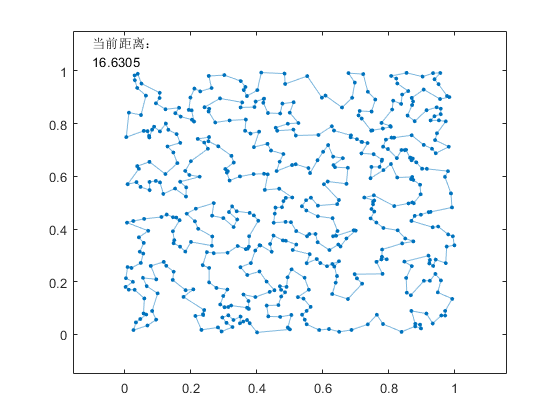


final_solution = solution.trajectory;
save('500_best_result.mat','final_solution');

clf;
hGraph = plot(G, 'XData',stopsX, 'YData',stopsY, "LineStyle","none", 'NodeLabel',{});
hold on;
highlight(hGraph, Gsol, 'LineStyle',"-");
text(-0.1, 1.07, ["当前距离：", num2str(dist' * solution.trajectory)]);

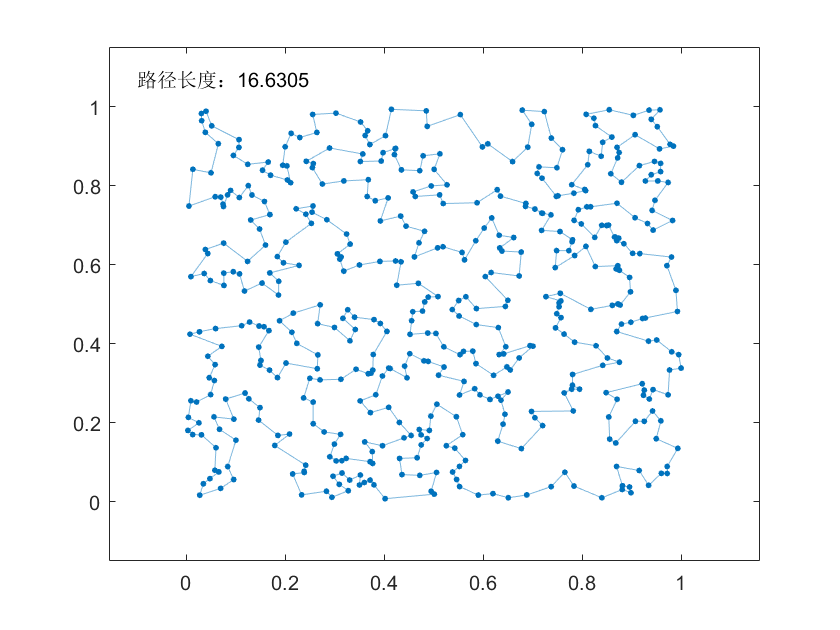

% final_solution = solution.trajectory;
% save('500_best_result.mat','final_solution');
load("500_best_result.mat");
Gsol = graph(idxs(final_solution, 1), idxs(final_solution, 2));
clf;
hGraph = plot(G, 'XData',stopsX, 'YData',stopsY, "LineStyle","none", 'NodeLabel',{});
hold on;
highlight(hGraph, Gsol, 'LineStyle',"-");
text(-0.1, 1.07, ["路径长度：" + num2str(dist' * final_solution)]);

load('mid_problem.mat');
Gsol = graph(idxs(solution.trajectory, 1), idxs(solution.trajectory, 2)); 
tourIDxs = conncomp(Gsol);
num_tours = max(tourIDxs);